clear all;
close all;
clc;

## Données du problème

L = 1; %longueur
Nx = 10; %nb de points de discrétisaton du domaine 
alpha = 1; %coefficient dans l'EDP (par exemple la conductivité thermique)
h = 1/(Nx+1); %pas d'espace
k = 1/4*h^2/alpha; %pas de temps
r=0.5;

## Schéma Crank-Nicholson 

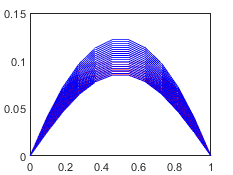



    Aimp = eye(Nx);
    Bexp = eye(Nx);
    C = 2*eye(Nx) - diag(diag(ones(Nx-1)),1) - diag(diag(ones(Nx-1)),-1);
    Aexp = eye(Nx) - alpha*k/h^2*C; % BUn+1 = AUn + kF
    Bimp = eye(Nx) + alpha*k/h^2*C; % BUn+1 = AUn + kF

    Ar = r*Aimp + (1-r)*Aexp;
    Br = r*Bimp + (1-r)*Bexp;
    X = linspace(h,L-h,Nx); %axe abscisses pour afficher U

    % initialisation de U
    U = zeros(Nx,1);
    for i = 1:Nx
        U(i) = 1/(2*alpha)*(i*h)*(1-i*h);
    end

    Ntc = 20;
    for n = 1:Ntc
        
        
        U = inv(Br)*Ar*U;
        Ure = [0
            U
            0];
        Xre = [0 X L];
        Uth = u(Xre,n*k,100,alpha);
        plot(Xre,Ure,'-r',Xre,Uth,'-b')
        hold on
        
        
    end